% Intro: Get Data and calculate some useful values

faithful = readtable("C:\Users\feyzi\OneDrive - Imperial College London\Year 3\Statistics\MATLAB Tutorials\faithful.csv")

faithful = 285×3 table
    waiting    duration    day
    _______    ________    ___

      80         4.02       1 
      71         2.15       1 
      57            4       1 
      80            4       1 
      75            4       1 
      77            2       1 
      60         4.38       1 
      86         4.28       1 
      77         2.03       1 
      56         4.83       1 
      81         1.83       1 
      50         5.45       1 
      89         1.62       1 
      54         4.87       1 
      90         4.38       1 
      73         1.77       1 


waiting = table2array(faithful(:,1))

waiting =     80
    71
    57
    80
    75
    77
    60
    86
    77
    56


max_waiting = max(waiting)

max_waiting = 108

min_waiting = min(waiting)

min_waiting = 43

median_waiting = median(waiting)

median_waiting = 76

mean_waiting = mean(waiting)

mean_waiting = 72.3895

mode_waiting = mode(waiting)

mode_waiting = 78

std_waiting = std(waiting)

std_waiting = 13.7092

var_waiting = var(waiting)

var_waiting = 187.9428

quantile_waiting = quantile(waiting, [0.25,0.5,0.75])

quantile_waiting =    60.0000   76.0000   82.2500


% Boxplot
hold off
waiting_boxplot = boxplot(waiting)

waiting_boxplot =     0.0004
    9.0002
   10.0001
   11.0001
   12.0001
   13.0001
   14.0001


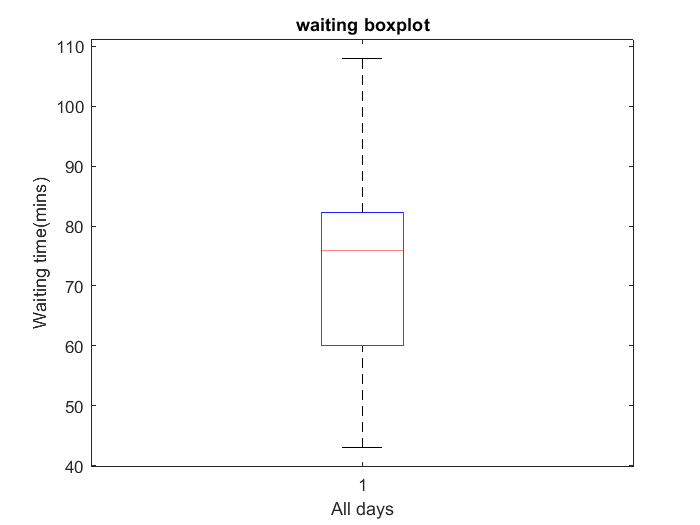

title("waiting boxplot")
xlabel("All days")
ylabel("Waiting time(mins)")

days = table2array(faithful(:,3))

days =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


waiting_by_day = boxplot(waiting, days, Whisker=2)

waiting_by_day =    10.0002   17.0001   24.0001   31.0001   38.0001   45.0001   52.0001   59.0001   66.0001   73.0001   80.0001   87.0001   94.0001  101.0001  108.0001
   11.0002   18.0001   25.0001   32.0001   39.0001   46.0001   53.0001   60.0001   67.0001   74.0001   81.0001   88.0001   95.0001  102.0001  109.0001
   12.0002   19.0001   26.0001   33.0001   40.0001   47.0001   54.0001   61.0001   68.0001   75.0001   82.0001   89.0001   96.0001  103.0001  110.0001
   13.0002   20.0001   27.0001   34.0001   41.0001   48.0001   55.0001   62.0001   69.0001   76.0001   83.0001   90.0001   97.0001  104.0001  111.0001
   14.0002   21.0001   28.0001   35.0001   42.0001   49.0001   56.0001   63.0001   70.0001   77.0001   84.0001   91.0001   98.0001  105.0001  112.0001
   15.0002   22.0001   29.0001   36.0001   43.0001   50.0001   57.0001   64.0001   71.0001   78.0001   85.0001   92.0001   99.0001  106.0001  113.0001
   16.0002   23.0001   30.0001   37.0001   44.0001   51.0001   58.0001   65.0

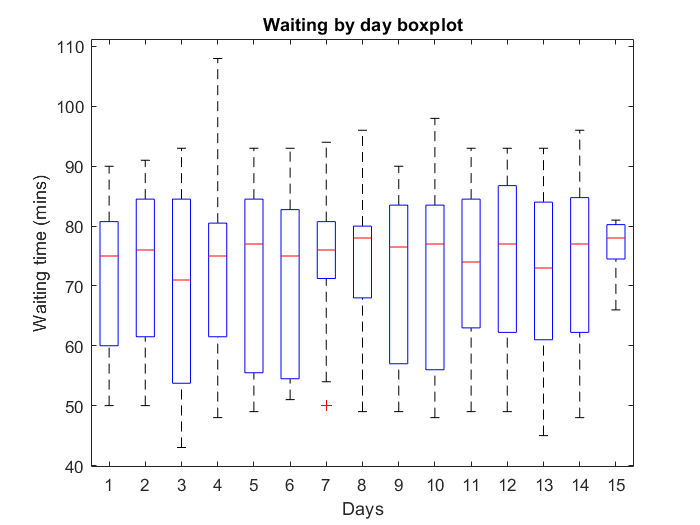

% Whiskers normally extend to at most 1.5 times IQR
title("Waiting by day boxplot")
xlabel("Days")
ylabel("Waiting time (mins)")

% Histograms and Kernel Density Plots

bins = linspace(min_waiting, max_waiting,11)

bins =    43.0000   49.5000   56.0000   62.5000   69.0000   75.5000   82.0000   88.5000   95.0000  101.5000  108.0000


bin_length = bins(2) - bins(1)

bin_length = 6.5000

freq = hist(waiting,11) %#ok<*HIST> 

freq =      7    42    27    19    19    57    59    38    15     1     1


my_hist = bar(bins, freq, 1) 

my_hist =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 1
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [43 49.5000 56 62.5000 69 75.5000 82 88.5000 95 101.5000 108]
        YData: [7 42 27 19 19 57 59 38 15 1 1]

  Show all properties


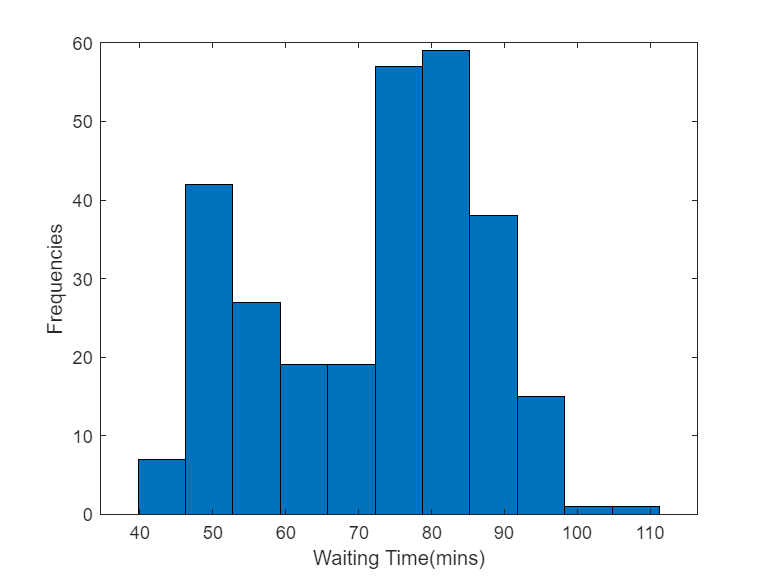

xlabel("Waiting Time(mins)")
ylabel("Frequencies")


relfreq = freq / length(waiting) / bin_length

relfreq =     0.0038    0.0227    0.0146    0.0103    0.0103    0.0308    0.0318    0.0205    0.0081    0.0005    0.0005


hold off

new_hist = bar(bins, relfreq, 1)

new_hist =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 1
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [43 49.5000 56 62.5000 69 75.5000 82 88.5000 95 101.5000 108]
        YData: [0.0038 0.0227 0.0146 0.0103 0.0103 0.0308 0.0318 0.0205 0.0081 5.3981e-04 5.3981e-04]

  Show all properties


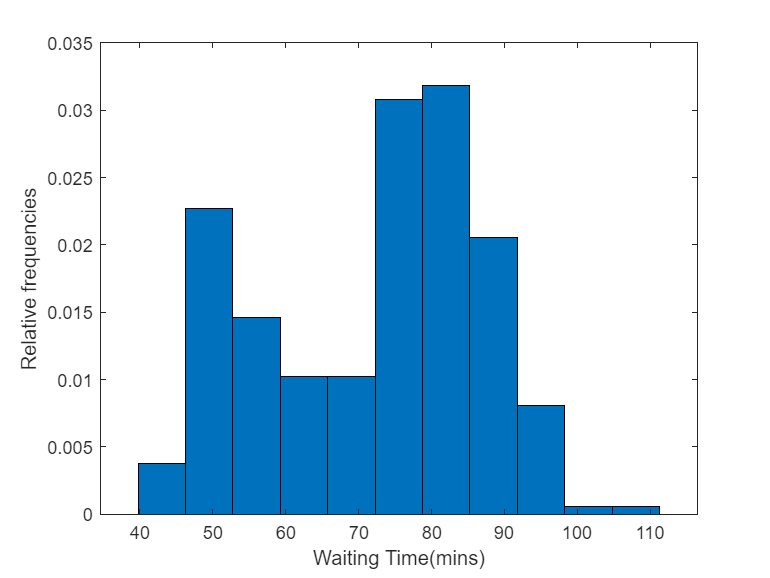

xlabel("Waiting Time(mins)")
ylabel("Relative frequencies")
hold on

[f,xi] = ksdensity(waiting, bins)

f =     0.0048    0.0142    0.0167    0.0133    0.0161    0.0279    0.0303    0.0198    0.0080    0.0017    0.0004


xi =    43.0000   49.5000   56.0000   62.5000   69.0000   75.5000   82.0000   88.5000   95.0000  101.5000  108.0000


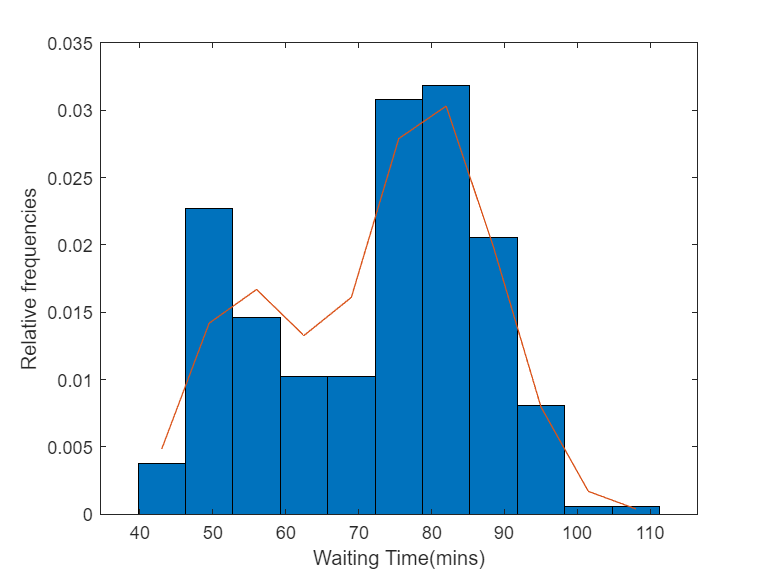

plot(xi,f)

% 20 bins
new_bins = linspace(min_waiting,max_waiting,20)

new_bins =    43.0000   46.4211   49.8421   53.2632   56.6842   60.1053   63.5263   66.9474   70.3684   73.7895   77.2105   80.6316   84.0526   87.4737   90.8947   94.3158   97.7368  101.1579  104.5789  108.0000


[f,xi] = ksdensity(waiting, new_bins)

f =     0.0048    0.0098    0.0146    0.0169    0.0164    0.0145    0.0130    0.0139    0.0182    0.0248    0.0302    0.0312    0.0278    0.0218    0.0151    0.0090    0.0045    0.0019    0.0007    0.0004


xi =    43.0000   46.4211   49.8421   53.2632   56.6842   60.1053   63.5263   66.9474   70.3684   73.7895   77.2105   80.6316   84.0526   87.4737   90.8947   94.3158   97.7368  101.1579  104.5789  108.0000


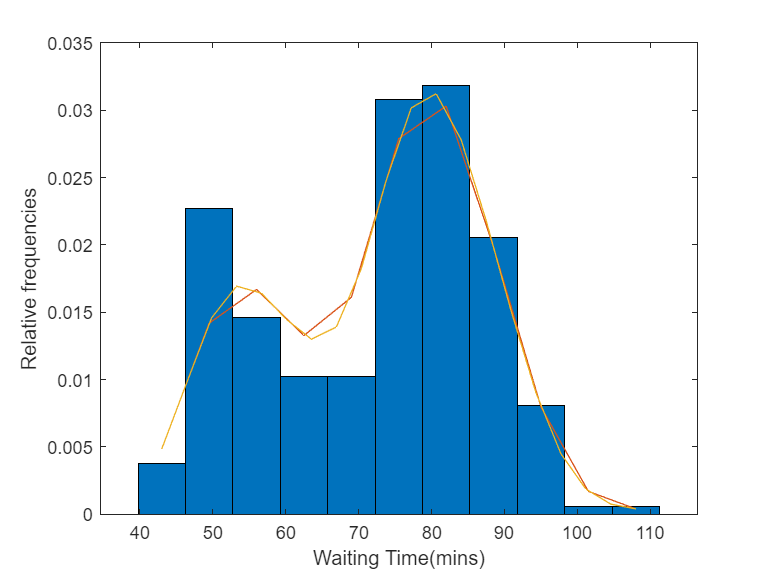

plot(xi,f)

% 50 bins
new_bins = linspace(min_waiting,max_waiting,50)

new_bins =    43.0000   44.3265   45.6531   46.9796   48.3061   49.6327   50.9592   52.2857   53.6122   54.9388   56.2653   57.5918   58.9184   60.2449   61.5714   62.8980   64.2245   65.5510   66.8776   68.2041   69.5306   70.8571   72.1837   73.5102   74.8367   76.1633   77.4898   78.8163   80.1429   81.4694   82.7959   84.1224   85.4490   86.7755   88.1020   89.4286   90.7551   92.0816   93.4082   94.7347   96.0612   97.3878   98.7143  100.0408  101.3673  102.6939  104.0204  105.3469  106.6735  108.0000


[f,xi] = ksdensity(waiting, new_bins)

f =     0.0048    0.0066    0.0086    0.0106    0.0126    0.0143    0.0157    0.0166    0.0170    0.0170    0.0166    0.0160    0.0152    0.0144    0.0137    0.0131    0.0129    0.0131    0.0138    0.0151    0.0169    0.0191    0.0216    0.0243    0.0268    0.0289    0.0304    0.0313    0.0314    0.0307    0.0295    0.0277    0.0256    0.0232    0.0206    0.0180    0.0154    0.0129    0.0105    0.0084    0.0065    0.0049    0.0035    0.0025    0.0018    0.0012    0.0009    0.0006    0.0005    0.0004


xi =    43.0000   44.3265   45.6531   46.9796   48.3061   49.6327   50.9592   52.2857   53.6122   54.9388   56.2653   57.5918   58.9184   60.2449   61.5714   62.8980   64.2245   65.5510   66.8776   68.2041   69.5306   70.8571   72.1837   73.5102   74.8367   76.1633   77.4898   78.8163   80.1429   81.4694   82.7959   84.1224   85.4490   86.7755   88.1020   89.4286   90.7551   92.0816   93.4082   94.7347   96.0612   97.3878   98.7143  100.0408  101.3673  102.6939  104.0204  105.3469  106.6735  108.0000


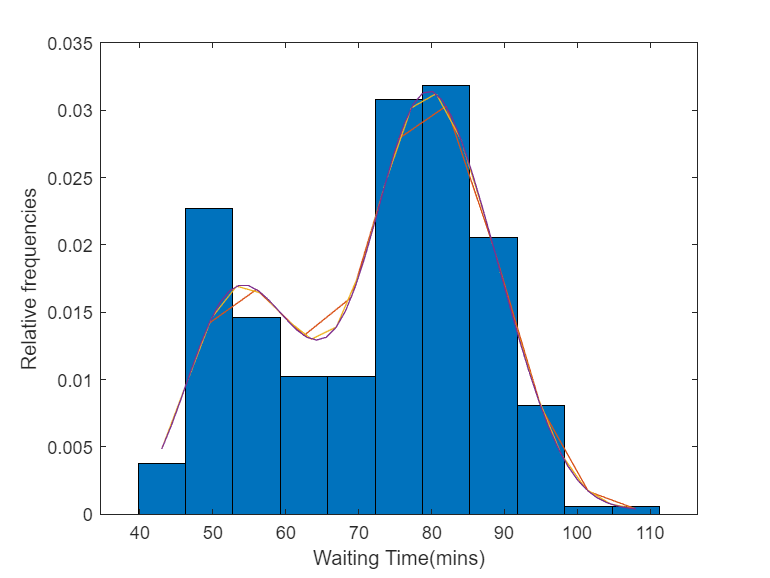

plot(xi,f)

% 100 bins
[f,xi] = ksdensity(waiting)

f =     0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0004    0.0005    0.0008    0.0011    0.0016    0.0022    0.0030    0.0040    0.0051    0.0064    0.0078    0.0093    0.0108    0.0122    0.0135    0.0147    0.0157    0.0164    0.0168    0.0170    0.0170    0.0168    0.0164    0.0159    0.0154    0.0148    0.0142    0.0137    0.0133    0.0130    0.0129    0.0131    0.0135    0.0142    0.0152    0.0164    0.0179    0.0197    0.0215    0.0234    0.0253    0.0271


xi =    27.7890   28.7528   29.7167   30.6806   31.6444   32.6083   33.5721   34.5360   35.4999   36.4637   37.4276   38.3914   39.3553   40.3192   41.2830   42.2469   43.2107   44.1746   45.1384   46.1023   47.0662   48.0300   48.9939   49.9577   50.9216   51.8855   52.8493   53.8132   54.7770   55.7409   56.7048   57.6686   58.6325   59.5963   60.5602   61.5240   62.4879   63.4518   64.4156   65.3795   66.3433   67.3072   68.2711   69.2349   70.1988   71.1626   72.1265   73.0904   74.0542   75.0181


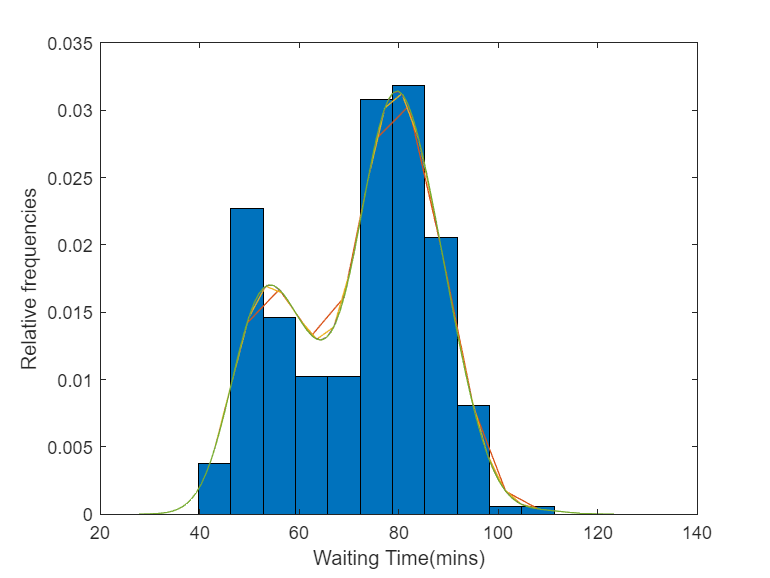

plot(xi,f)

% 3 Plotting consecutive eruption waiting times

hold off

days = table2array(faithful(:,3))

days =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


first = 1

last = 19

x =     1.0000    1.9444    2.8889    3.8333    4.7778    5.7222    6.6667    7.6111    8.5556    9.5000   10.4444   11.3889   12.3333   13.2778   14.2222   15.1667   16.1111   17.0556   18.0000


y =     80
    71
    57
    80
    75
    77
    60
    86
    77
    56


first = 20

last = 39

x =     1.0000    1.9474    2.8947    3.8421    4.7895    5.7368    6.6842    7.6316    8.5789    9.5263   10.4737   11.4211   12.3684   13.3158   14.2632   15.2105   16.1579   17.1053   18.0526   19.0000


y =     82
    84
    54
    85
    58
    79
    57
    88
    68
    76


first = 40

last = 60

x =     1.0000    1.9500    2.9000    3.8500    4.8000    5.7500    6.7000    7.6500    8.6000    9.5500   10.5000   11.4500   12.4000   13.3500   14.3000   15.2500   16.2000   17.1500   18.1000   19.0500   20.0000


y =     48
    93
    54
    86
    53
    78
    52
    83
    60
    87


first = 61

last = 80

x =     1.0000    1.9474    2.8947    3.8421    4.7895    5.7368    6.6842    7.6316    8.5789    9.5263   10.4737   11.4211   12.3684   13.3158   14.2632   15.2105   16.1579   17.1053   18.0526   19.0000


y =    108
    50
    77
    57
    80
    61
    82
    48
    81
    73


first = 81

last = 100

x =     1.0000    1.9474    2.8947    3.8421    4.7895    5.7368    6.6842    7.6316    8.5789    9.5263   10.4737   11.4211   12.3684   13.3158   14.2632   15.2105   16.1579   17.1053   18.0526   19.0000


y =     81
    74
    59
    81
    66
    87
    53
    80
    50
    87


first = 101

last = 121

x =     1.0000    1.9500    2.9000    3.8500    4.8000    5.7500    6.7000    7.6500    8.6000    9.5500   10.5000   11.4500   12.4000   13.3500   14.3000   15.2500   16.2000   17.1500   18.1000   19.0500   20.0000


y =     56
    89
    51
    79
    58
    82
    52
    88
    52
    78


first = 122

last = 140

x =     1.0000    1.9444    2.8889    3.8333    4.7778    5.7222    6.6667    7.6111    8.5556    9.5000   10.4444   11.3889   12.3333   13.2778   14.2222   15.1667   16.1111   17.0556   18.0000


y =     54
    76
    80
    81
    59
    86
    78
    71
    77
    76


first = 141

last = 160

x =     1.0000    1.9474    2.8947    3.8421    4.7895    5.7368    6.6842    7.6316    8.5789    9.5263   10.4737   11.4211   12.3684   13.3158   14.2632   15.2105   16.1579   17.1053   18.0526   19.0000


y =     79
    72
    78
    77
    79
    75
    78
    64
    80
    49


first = 161

last = 180

x =     1.0000    1.9474    2.8947    3.8421    4.7895    5.7368    6.6842    7.6316    8.5789    9.5263   10.4737   11.4211   12.3684   13.3158   14.2632   15.2105   16.1579   17.1053   18.0526   19.0000


y =     75
    78
    87
    69
    55
    83
    49
    82
    57
    84


first = 181

last = 200

x =     1.0000    1.9474    2.8947    3.8421    4.7895    5.7368    6.6842    7.6316    8.5789    9.5263   10.4737   11.4211   12.3684   13.3158   14.2632   15.2105   16.1579   17.1053   18.0526   19.0000


y =     78
    52
    98
    48
    78
    79
    65
    84
    50
    83


first = 201

last = 220

x =     1.0000    1.9474    2.8947    3.8421    4.7895    5.7368    6.6842    7.6316    8.5789    9.5263   10.4737   11.4211   12.3684   13.3158   14.2632   15.2105   16.1579   17.1053   18.0526   19.0000


y =     49
    88
    51
    78
    85
    65
    75
    77
    69
    92


first = 221

last = 239

x =     1.0000    1.9444    2.8889    3.8333    4.7778    5.7222    6.6667    7.6111    8.5556    9.5000   10.4444   11.3889   12.3333   13.2778   14.2222   15.1667   16.1111   17.0556   18.0000


y =     93
    50
    87
    77
    74
    72
    82
    74
    80
    49


first = 240

last = 259

x =     1.0000    1.9474    2.8947    3.8421    4.7895    5.7368    6.6842    7.6316    8.5789    9.5263   10.4737   11.4211   12.3684   13.3158   14.2632   15.2105   16.1579   17.1053   18.0526   19.0000


y =     80
    89
    45
    93
    72
    71
    54
    79
    74
    65


first = 260

last = 278

x =     1.0000    1.9444    2.8889    3.8333    4.7778    5.7222    6.6667    7.6111    8.5556    9.5000   10.4444   11.3889   12.3333   13.2778   14.2222   15.1667   16.1111   17.0556   18.0000


y =     86
    75
    73
    53
    82
    93
    77
    54
    96
    48


first = 279

last = 285

x =     1.0000    1.8333    2.6667    3.5000    4.3333    5.1667    6.0000


y =     78
    81
    78
    76
    74
    81
    66


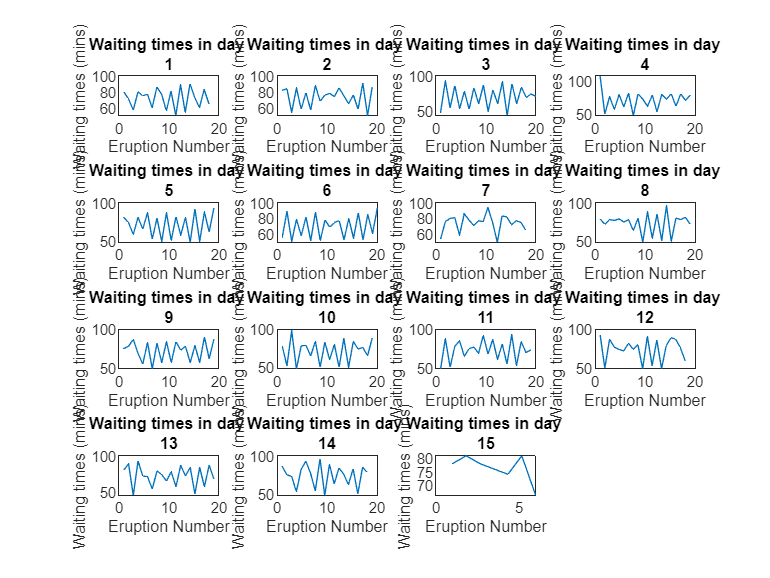


for i = 1.0:1:15.0 
%     Find first and last entry for day
    first = find(days == i, 1)
    last = find(days == i, 1, "last")

    subplot(4,4,i)
    x = linspace(1,last-first, last-first +1)
    y = waiting(first:last)
    plot(x,y)
    ylabel("Waiting times (mins)")
    xlabel("Eruption Number")
    title(["Waiting times in day ", num2str(i)])
    set(gca, "FontSize", 8) 

end

% Part 4 Scatterplots and Regression

n = length(waiting)

n = 285

duration = table2array(faithful(:,2))

duration =     4.0200
    2.1500
    4.0000
    4.0000
    4.0000
    2.0000
    4.3800
    4.2800
    2.0300
    4.8300


% Not sure how to deal with this here
lagduration = lagmatrix(duration,1)

lagduration =        NaN
    4.0200
    2.1500
    4.0000
    4.0000
    4.0000
    2.0000
    4.3800
    4.2800
    2.0300


clf
p1 = scatter(lagduration,waiting)

p1 =   Scatter with properties:

              XData: [NaN 4.0200 2.1500 4 4 4 2 4.3800 4.2800 2.0300 4.8300 1.8300 5.4500 1.6200 4.8700 4.3800 1.7700 4.6700 2 4.7300 4.2200 1.9000 4.9700 2 4 2 4 2.8300 4.5000 4.0700 3.7200 3.5200 4.4700 2.2200 4.8800 2.6000 4.1500 2.2000 4.7700 … ]
              YData: [80 71 57 80 75 77 60 86 77 56 81 50 89 54 90 73 60 83 65 82 84 54 85 58 79 57 88 68 76 78 74 85 75 65 76 58 91 50 87 48 93 54 86 53 78 52 83 60 87 49 80 60 92 43 89 60 84 69 74 71 108 50 77 57 80 61 82 48 81 73 62 79 54 80 73 81 … ]
              ZData: [1×0 double]
           SizeData: 36
              CData: [0 0.4470 0.7410]
             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000

  Show 

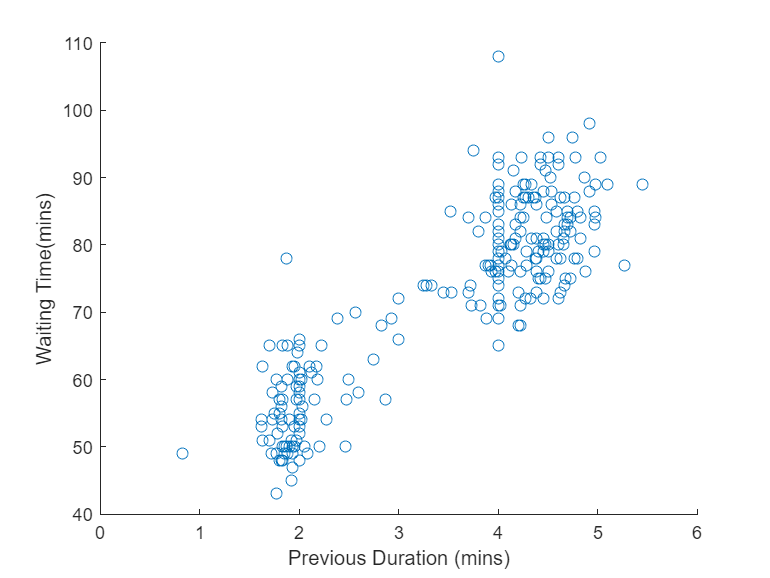

ylabel("Waiting Time(mins)")
xlabel("Previous Duration (mins)")

% Do Linear Regression
Y = waiting

Y =     80
    71
    57
    80
    75
    77
    60
    86
    77
    56


isvector(Y)

ans = logical
   1


X = [ ones(n,1) lagduration ] 

X =     1.0000       NaN
    1.0000    4.0200
    1.0000    2.1500
    1.0000    4.0000
    1.0000    4.0000
    1.0000    4.0000
    1.0000    2.0000
    1.0000    4.3800
    1.0000    4.2800
    1.0000    2.0300


% Why Wont this work
B = regress(y,X)

Error using regress (line 62)
Y must be a vector and must have the same number of rows as X.

% Calculate line of best fit
waitingest = B(1) + B(2)*lagduration;

hold on 
plot(waitingest,lagduration)

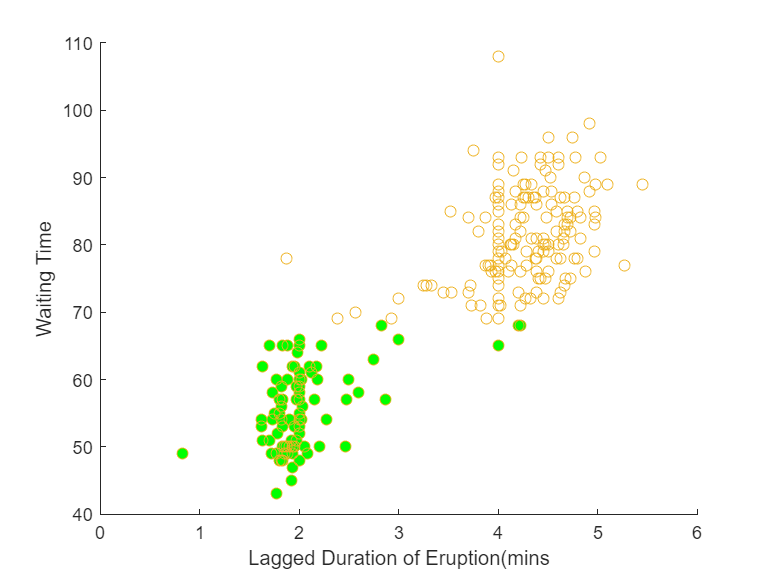

% Part 5- K means clustering

scatter(X(:,2),waiting)
xlabel("Lagged Duration of Eruption(mins")
ylabel("Waiting Time")

C = kmeans([X, waiting], 2);

C

C =    NaN
     1
     2
     1
     1
     1
     2
     1
     1
     2


% define some colours
col{1} = "r"

col = 1×2 cell array
    {["r"]}    {["g"]}


col{2} = "g"

col = 1×2 cell array
    {["r"]}    {["g"]}


% Overlay two scatterplots with two groups colored differently

% for each class


loc1 = find(C == 1)

loc1 =      2
     4
     5
     6
     8
     9
    11
    13
    15
    16


loc2 = find(C ==2)

loc2 =      3
     7
    10
    12
    14
    17
    19
    22
    24
    26


waiting1 = waiting([loc1])

waiting1 =     71
    80
    75
    77
    86
    77
    81
    89
    90
    73


waiting2 = waiting([loc2])

waiting2 =     57
    60
    56
    50
    54
    60
    65
    54
    58
    57


duration1 = X([loc1],2)

duration1 =     4.0200
    4.0000
    4.0000
    4.0000
    4.3800
    4.2800
    4.8300
    5.4500
    4.8700
    4.3800


duration2 = X([loc2],2) %#ok<*NBRAK> 

duration2 =     2.1500
    2.0000
    2.0300
    1.8300
    1.6200
    1.7700
    2.0000
    1.9000
    2.0000
    2.0000


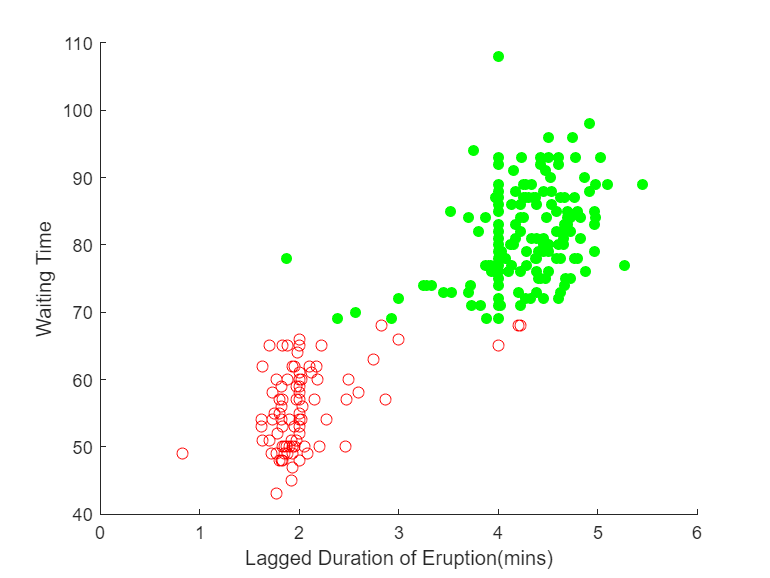


% Now plot the two groups
clf
scatter(duration1, waiting1, col{2},"filled")
hold on

scatter(duration2, waiting2,col{1})
xlabel("Lagged Duration of Eruption(mins)")
ylabel("Waiting Time")


newdata = readtable("faithful15.csv");

newdata

newdata = 14×3 table
    waiting15    duration15    day15
    _________    __________    _____

       84           1.93        15  
       48           4.33        15  
       93           1.67        15  
       47           4.77        15  
       87           1.95        15  
       51           4.68        15  
       78           1.93        15  
       54           4.42        15  
       87           2.13        15  
       52           4.08        15  
       85           2.07        15  
       58              4        15  
       88              4        15  
       79              2        15  


clf
lagduration_new = lagmatrix(table2array(newdata(:,2)), 1)

lagduration_new =        NaN
    1.9300
    4.3300
    1.6700
    4.7700
    1.9500
    4.6800
    1.9300
    4.4200
    2.1300


lagduration_new(1,1) = 4

lagduration_new =     4.0000
    1.9300
    4.3300
    1.6700
    4.7700
    1.9500
    4.6800
    1.9300
    4.4200
    2.1300


waitingd15 = table2array(newdata(:,1))

waitingd15 =     84
    48
    93
    47
    87
    51
    78
    54
    87
    52


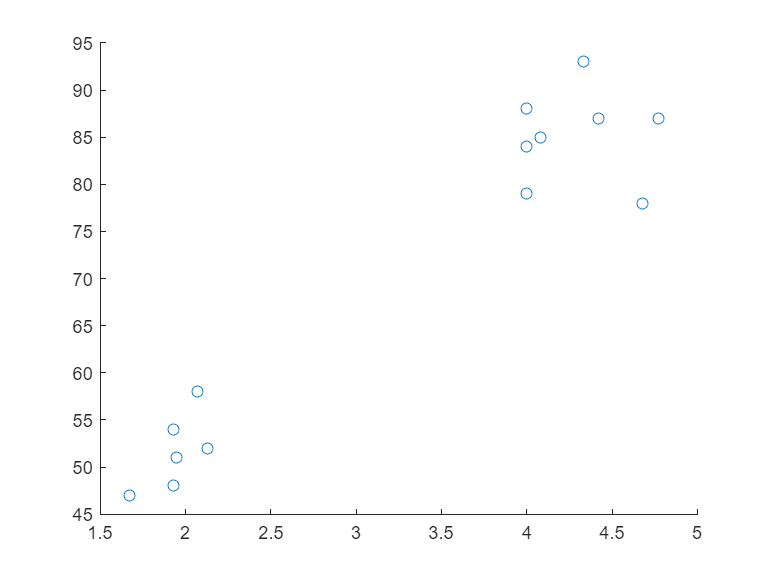


scatter(lagduration_new, waitingd15)